%%Problema Motor de inducción 1 (2.03)
%Se tiene un Motor de Inducción 3Ø, en "Y o estrella", de 600 V,
%250 HP, 6 polos, 50Hz.
clear 
clc
%Datos del motor de inducción
m1= 3

m1 =      3


V1 = 600 %(V)

V1 =    600


Hp = 250 

Hp =    250


p = 6 %polos

p =      6


f = 50 %Hz

f =     50



%Datos tipicos en la tabla de un motor
X1 = 0.2j; % (Ω)
R1 = 0.05; % (Ω)
X2 = 0.3j; % (Ω) (rotor primario?)
R2 = 0.06; % (Ω) (rotor primario?)

Xm = 10j; % (Ω)
%solo no dieron el Rf o perdidas de hierro

%Hallar el torque máximo.
%Hallar la potencia mecánica máxima.
disp('Circuito equivalente del motor de indución')

Circuito equivalente del motor de indución


disp('Para solucionarlo se realiza un equivalente de thevenin')

Para solucionarlo se realiza un equivalente de thevenin


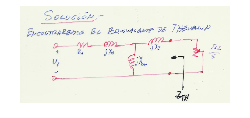

imshow(imread("2.png"))


% Zth o impedancia de thevenin 
disp('-Zth o impedancia de thevenin- ')

-Zth o impedancia de thevenin- 



Zth = (((R1 + X1)*Xm)/(R1+(X1+Xm)))+ X2

Zth =          0.0480572842828652 +     0.496314006295504i


[angleZth, ratioZth] = cart2pol(real(Zth), imag(Zth))

angleZth =           1.47426886204851


ratioZth =          0.498635232828305


%Radianes a grados

disp('Radianes a grados')

Radianes a grados



angleZth = rad2deg(angleZth)

angleZth =           84.4693836629344



disp('-----------------')

-----------------



%Vth o tensión de thevenin
disp('-Vth o tensión de thevenin- ')

-Vth o tensión de thevenin- 



Vth =  (((V1)/(sqrt(3)))*((Xm)/(R1+(X1+Xm))))

Vth =            339.609644850951 +      1.66475316103408i


[angleVth, ratioVth] = cart2pol(real(Vth), imag(Vth))

angleVth =        0.00490192152144919


ratioVth =           339.613725103796


%Radianes a grados

disp('Radianes a grados')

Radianes a grados



angleVth = rad2deg(angleVth)

angleVth =          0.280859414683386


disp('-----------------')

-----------------



% A) Torque máximo
disp('A) Torque máximo')

A) Torque máximo



%Rth y jXth son el valor real e imaginario de la impedancia Zth

disp('Circuito equivalente de thevenin que muestra la impedancia obtenida')

Circuito equivalente de thevenin que muestra la impedancia obtenida


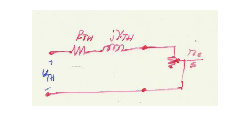

imshow(imread("3.png"))


%Deslizamiento donde el torque es máximo
Rth = real(Zth)

Rth =         0.0480572842828652


Xth = imag(Zth)

Xth =          0.496314006295504


disp('Deslizamiento donde el torque es máximo')

Deslizamiento donde el torque es máximo


Stm = (R2)/(sqrt((Rth^2)+(Xth^2)))

Stm =          0.120328440611135


%sad = round(Stm,3)
%Obteniendo Tmáx

ns = (120*f)/p %rpm

ns =         1000


ws = (2*pi)*(ns/60)

ws =            104.71975511966


I2 = ((ratioVth^2)/(((Rth+(R2/Stm))^2)+(Xth^2)))

I2 =           211550.657701329


Tmax= (1/ws)*m1*(I2)*(R2/Stm) %(N/m)

Tmax =           3021.96881583653



disp('-----------------')

-----------------


% A) Potencia mecánica máxima
disp('A) Potencia mecánica máxima')

A) Potencia mecánica máxima


%Se produce cuando se obtiene la máxima transferencia de potencia
%a través del circuito:

disp('Circuito de thevenin en máx transferencia de potencia')

Circuito de thevenin en máx transferencia de potencia


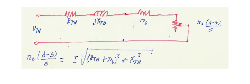

imshow(imread("4.png"))


disp('igualdad de R2/S y deslizamiento de potencia máxima')

igualdad de R2/S y deslizamiento de potencia máxima


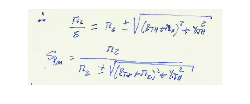

imshow(imread("5.png"))

%Deslizamiento en con potencia mecánica máxima
SpMax = R2 /(R2 + sqrt((Rth+R2)^2+(Xth)^2)) 

SpMax =          0.105644792952289


SpMin = R2 /(R2 - sqrt((Rth+R2)^2+(Xth)^2))

SpMin =         -0.133946238142999



I2new = (ratioVth^2) / ((Rth+(R2/SpMax))^2+Xth^2)

I2new =           184309.549322187



Pmax = ((m1)*(I2new)*(R2)*((1-SpMax)/SpMax))%KW

Pmax =           280855.081418775
